# **Controllo di un camion con rimorchio (23/01/2023)**

Si consideri un sistema caratterizzato da un camion con rimorchio.

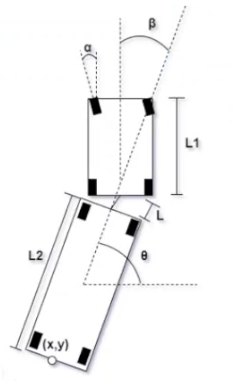

Il modello non lineare che ne descrive la cinematica è il seguente:


$$\begin{cases}
\dot{x}_P = v\cos\beta\cdot \left(1 + \frac{L}{L_1}\tan\beta\cdot\tan\alpha\right) \cdot \cos\theta \ \ \\
\dot{y}_P = v\cos\beta\cdot \left(1 + \frac{L}{L_1}\tan\beta\cdot\tan\alpha\right) \cdot \sin\theta \ \  \\
\dot{\theta} = v \cdot \left(\frac{\sin\beta}{L_2}-\frac{L}{L_1L_2}\right) \cdot \cos\beta \cdot \tan\alpha \ \ \ \ \ \  \\
\dot{\beta} = v \cdot \left( \frac{\tan\alpha}{L_1} - \frac{\sin\beta}{L_2} + \frac{L}{L_1L_2} \cdot \cos\beta \cdot \tan\alpha \right)
\end{cases}$$


avendo considerato come vettori di ingresso e di uscita:


$$x=\left\lbrack \begin{array}{c}
x_P \\
y_P \\
\theta \\
\beta 
\end{array}\right\rbrack ,\;\;\;\;\;\;\;\;\;y=x$$


La seguente tabella elenca i parametri del veicolo:

L'obiettivo del problema è quello di progettare un controllore MPC non lineare che sia in grado di individuare un percorso ottimale per parcheggiare automaticamente il camion con rimorchio dalla sua posizione iniziale alla posizione desiderata.

- Calcolare e specificare lo Jacobiano analitico per la funzione di stato e per la funzione di uscita

- Siano $T_s =0\ldotp 5\;\mathrm{s}$, $H_p =12$ e $H_c =5$. Inizializzare il controllore MPC con i parametri appropriati. Validare l'oggetto MPC. Eseguire una simulazione della durata di $10\;\mathrm{s}$ e commentare i risultati ottenuti.

- L'angolo di sterzata del camion deve rimanere nel range $\pm 45\;\deg$. La massima velocità in avanti e la massima velocità in retromarcia devono essere di $10\;\frac{m}{\mathrm{s}}$. L'angolo tra il camion ed il rimorchio non può superare i $\pm 90\;\deg$ a causa delle limitazioni meccaniche. Vincolare il controllore opportunamente. Eseguire una simulazione della durata di $10\;\mathrm{s}$ e commentare i risultati ottenuti. I vincoli hanno avuto effetto?

- Si vogliono rispettare i seguenti requisiti: errore di posizione a regime $\pm 1\;\mathrm{m}$, errore angolare a regime (su $\theta$) $\pm 1\;\deg$, tempo di manovra $<6\;\mathrm{s}$, tempo di parcheggio minimo. Eseguire il tuning del controllore per rispettare i requisiti elencati. Spiegare tutte le scelte di progetto e commentare i risultati ottenuti.

- Analizzae il tempo computazionale richiesto per l'aggiornamento di ciascun movimento. È possibile controllare il sistema in realtime?

- Plottare l'evoluzione del costo nel tempo e commentare il risultato.

## Implementazione del sistema

% Operazioni preliminari
close all;
clear all; 
clc;

### Funzione di stato

Poiché il sistema descritto è non lineare, occorre dichiarare separatamente la funzione di stato ([`ttStateFunction.m`](matlab:open('./ttStateFunction.m'))`).`

### Funzione di uscita

Poiché il sistema descritto è non lineare, occorre dichiarare separatamente la funzione di uscita ([`ttOutputFunction.m`](matlab:open('./ttOutputFunction.m'))`).`

## Implementazione del controllore

Una volta implementato il sistema non lineare attraverso le sue funzioni di stato e di uscita, è necessario definire il controllore MPC.

% Numero di stati
nx = 4;

% Numero di uscite
ny = 4;

% Numero di ingressi
nu = 2;

Il fatto che il numero di uscite sia uguale al numero di stati implica che tutti gli stati del sistema siano misurabili.

### Definizione del controllore

% Controllore MPC
nlmpcobj = nlmpc(nx,ny,nu);

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.


Poiché il numero di uscite è maggiore del numero di ingressi, di default MATLAB assegna un peso nullo sulle uscite eccedenti il numero di ingressi. In questo caso, poiché gli ingressi sono 2 e le uscite sono 4, alla terza ed alla quarta uscita viene assegnato peso nullo.

### Funzioni del sistema

Occorre specificare la funzione di stato e la funzione di uscita del sistema non lineare.

% Funzione di stato
nlmpcobj.Model.StateFcn = 'ttStateFunction';

% Funzione di uscita (inutile)
% nlmpcobj.Model.OutputFcn = 'ttOutputFunction';

## Richiesta 1

In primo luogo devono essere noti lo Jacobiano analitico per la funzione di stato e lo Jacobiano analitico per la funzione di uscita.

### Calcolo dello Jacobiano analitico della funzione di stato

La funzione di stato può essere differenziata rispetto alle variabili di stato ed alle variabili di ingresso.

Differenziando la funzione di stato rispetto alle variabili di stato si ottiene la matrice:


$$A=\frac{\partial f\left(x,u\right)}{\partial x}=\left\lbrack \begin{array}{cccc}
\frac{\partial f_1 }{\partial x_1 } & \frac{\partial f_1 }{\partial x_2 } & \frac{\partial f_1 }{\partial x_3 } & \frac{\partial f_1 }{\partial x_4 }\\
\frac{\partial f_2 }{\partial x_1 } & \frac{\partial f_2 }{\partial x_2 } & \frac{\partial f_2 }{\partial x_3 } & \frac{\partial f_2 }{\partial x_4 }\\
\frac{\partial f_3 }{\partial x_1 } & \frac{\partial f_3 }{\partial x_2 } & \frac{\partial f_3 }{\partial x_3 } & \frac{\partial f_3 }{\partial x_4 }\\
\frac{\partial f_4 }{\partial x_1 } & \frac{\partial f_4 }{\partial x_2 } & \frac{\partial f_4 }{\partial x_3 } & \frac{\partial f_4 }{\partial x_4 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 0 & v\;\cos \;\beta \cdot \left(1+\frac{L}{L_1 }\tan \;\beta \cdot \tan \;\alpha \right)\cdot \left(-\sin \;\theta \right) & v\cdot \left(-\sin \;\beta +\frac{L}{L_1 }\cos \;\beta \cdot \tan \;\alpha \right)\cdot \cos \;\theta \\
0 & 0 & v\;\cos \;\beta \cdot \left(1+\frac{L}{L_1 }\tan \;\beta \cdot \tan \;\alpha \right)\cdot \cos \;\theta  & v\cdot \left(-\sin \;\beta +\frac{L}{L_1 }\cos \;\beta \cdot \tan \;\alpha \right)\cdot \sin \;\theta \\
0 & 0 & 0 & v\cdot \left(\frac{\cos \;\beta }{L_2 }+\frac{L}{L_1 L_2 }\sin \;\beta \cdot \tan \;\alpha \right)\\
0 & 0 & 0 & v\cdot \left(-\frac{\cos \;\beta }{L_2 }+\frac{L}{L_1 L_2 }\sin \;\beta \cdot \tan \;\alpha \right)
\end{array}\right\rbrack$$


Differenziando la funzione di stato rispetto alle variabili di ingresso si ottiene la matrice:


$$B=\frac{\partial f\left(x,u\right)}{\partial u}=\left\lbrack \begin{array}{cc}
\frac{\partial f_1 }{\partial u_1 } & \frac{\partial f_1 }{\partial u_2 }\\
\frac{\partial f_2 }{\partial u_1 } & \frac{\partial f_2 }{\partial u_2 }\\
\frac{\partial f_3 }{\partial u_1 } & \frac{\partial f_3 }{\partial u_2 }\\
\frac{\partial f_4 }{\partial u_1 } & \frac{\partial f_4 }{\partial u_2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
v\cdot \cos \;\beta \cdot \frac{L}{L_1 }\cdot \frac{\tan \;\beta }{\cos^2 \;\alpha }\cdot \cos \;\theta  & \cos \;\beta \cdot \left(1+\frac{L}{L_1 }\cdot \tan \;\beta \cdot \tan \;\alpha \right)\cdot \cos \;\theta \\
v\cdot \cos \;\beta \cdot \frac{L}{L_1 }\cdot \frac{\tan \;\beta }{\cos^2 \;\alpha }\cdot \sin \;\theta  & \cos \;\beta \cdot \left(1+\frac{L}{L_1 }\cdot \tan \;\beta \cdot \tan \;\alpha \right)\cdot \sin \;\theta \\
v\cdot \left(-\frac{L}{L_1 L_2 }\cdot \frac{\cos \;\beta }{\cos^2 \;\alpha }\right) & \frac{\sin \;\beta }{L_2 }-\frac{L}{L_1 L_2 }\cdot \cos \;\beta \cdot \tan \;\alpha \\
v\cdot \left(\frac{1}{L_1 \cdot \cos^2 \;\alpha }+\frac{L}{L_1 L_2 }\cdot \frac{\cos \;\beta }{\cos^2 \;\alpha }\right) & \frac{\tan \;\alpha }{L_1 }-\frac{\sin \;\beta }{L_2 }+\frac{L}{L_1 L_2 }\cdot \cos \;\beta \cdot \tan \;\alpha 
\end{array}\right\rbrack$$


I risultati ottenuti permettono di definire la funzione per lo Jacobiano analitico della funzione di stato ([`ttStateJacobian.m`](matlab:open('./ttStateJacobian.m'))).

% Jacobiano analitico della funzione di stato
nlmpcobj.Jacobian.StateFcn = 'ttStateJacobian';

### Calcolo dello Jacobiano analitico della funzione di uscita

La funzione di uscita può essere differenziata rispetto alle variabili di stato ed alle variabili di ingresso.

Differenziando la funzione di uscita rispetto alle variabili di stato si ottiene la matrice:


$$C=\frac{\partial g\left(x,u\right)}{\partial x}=\left\lbrack \begin{array}{cccc}
\frac{\partial g_1 }{\partial x_1 } & \frac{\partial g_1 }{\partial x_2 } & \frac{\partial g_1 }{\partial x_3 } & \frac{\partial g_1 }{\partial x_4 }\\
\frac{\partial g_2 }{\partial x_1 } & \frac{\partial g_2 }{\partial x_2 } & \frac{\partial g_2 }{\partial x_3 } & \frac{\partial g_2 }{\partial x_4 }\\
\frac{\partial g_3 }{\partial x_1 } & \frac{\partial g_3 }{\partial x_2 } & \frac{\partial g_3 }{\partial x_3 } & \frac{\partial g_3 }{\partial x_4 }\\
\frac{\partial g_4 }{\partial x_1 } & \frac{\partial g_4 }{\partial x_2 } & \frac{\partial g_4 }{\partial x_3 } & \frac{\partial g_4 }{\partial x_4 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Differenziando la funzione di uscita rispetto alle variabili di ingresso si ottiene la matrice identicamente nulla (che viene omessa):


$$D=\frac{\partial g\left(x,u\right)}{\partial u}=\left\lbrack \begin{array}{cc}
\frac{\partial g_1 }{\partial u_1 } & \frac{\partial g_1 }{\partial u_2 }\\
\frac{\partial g_2 }{\partial u_1 } & \frac{\partial g_2 }{\partial u_2 }\\
\frac{\partial g_3 }{\partial u_1 } & \frac{\partial g_3 }{\partial u_2 }\\
\frac{\partial g_4 }{\partial u_1 } & \frac{\partial g_4 }{\partial u_2 }
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
0 & 0\\
0 & 0
\end{array}\right\rbrack$$


I risultati ottenuti permettono di definire la funzione per lo Jacobiano analitico della funzione di uscita ([`ttOutputJacobian.m`](matlab:open('./ttOutputJacobian.m'))).

% Jacobiano analitico della funzione di uscita
nlmpcobj.Jacobian.OutputFcn = 'ttOutputJacobian';

### Verifica della correttezza dei calcoli

Per verificare se lo Jacobiano analitico per la funzione di stato e lo Jacobiano analitico per la funzione di uscita siano stati calcolati correttamente, è possibile validare il comportamento delle funzioni a fronte di un set di valori iniziali di variabili di stato e di ingressi.

% Stato
xk = zeros(4,1);

% Ingresso (con rumore)
mv = [0.1; 0.2];

% Verifica
validateFcns(nlmpcobj,xk,mv);

Model.StateFcn is OK.
Jacobian.StateFcn is OK.
No output function specified. Assuming "y = x" in the prediction model.
Analysis of user-provided model, cost, and constraint functions complete.


## Richiesta 2

Si vuole controllare il camion con rimorchio in modo da raggiungere la posizione di riferimento.

% Riferimento
ref = [1, -25, pi/2, 0];

### Parametri del controllore

Si definiscono innanzitutto i parametri del controllore:

% Periodo di campionamento
Ts = 0.5;

% Orizzonte di predizione
Hp = 12;

% Orizzonte di controllo
Hc = 5;

e li si assegnano al controllore accedendo alle rispettive proprietà.

% Periodo di campionamento
nlmpcobj.Ts = Ts;

% Orizzonte di predizione
nlmpcobj.PredictionHorizon = Hp;

% Orizzonte di controllo
nlmpcobj.ControlHorizon = Hc;

### Simulazione del controllo

Per verificare il corretto funzionamento del controllo, si esegue una simulazione di 10 secondi.

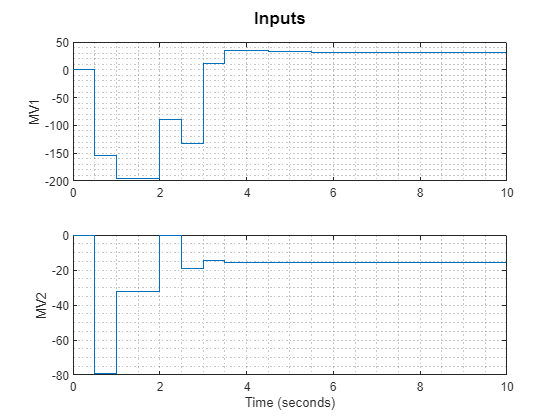

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

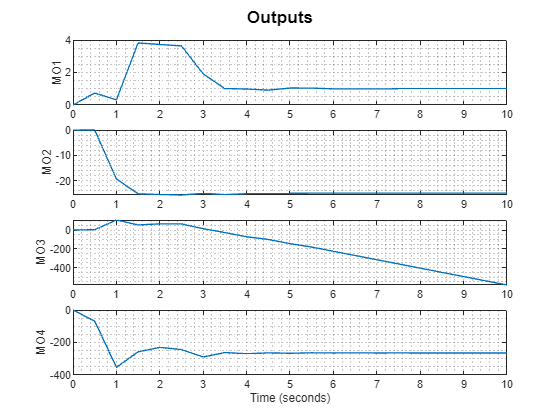


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

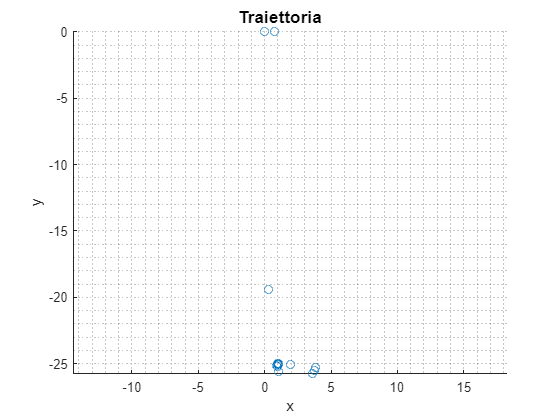


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione del controllo evidenziano un inseguimento del riferimento soddisfacente per le prime due variabili di uscita.

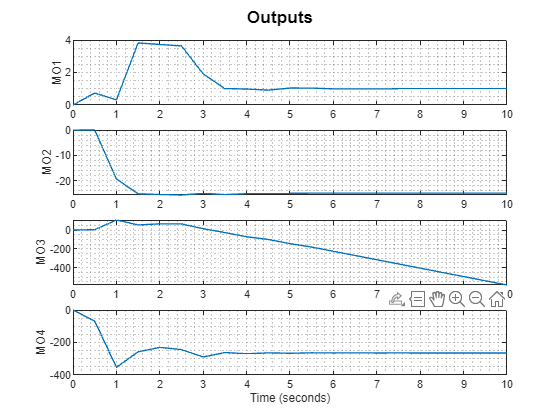

### Scelta dei pesi sulle uscite

L'andamento della terza variabile di uscita invece diverge a causa di un peso ad essa associato nullo, dovuto ad un numero di ingressi minore a quello di uscite. È quindi opportuno definire manualmente i pesi, dando maggiore importanza alla terza uscita.

% Peso associato alla prima uscita
nlmpcobj.Weights.OutputVariables(1) = 1;

% Peso associato alla seconda uscita
nlmpcobj.Weights.OutputVariables(2) = 1;

% Peso associato alla terza uscita
nlmpcobj.Weights.OutputVariables(3) = 1;

Si esegue nuovamente la simulazione per verificare se la modifica sui pesi associati alle uscite abbia effetto.

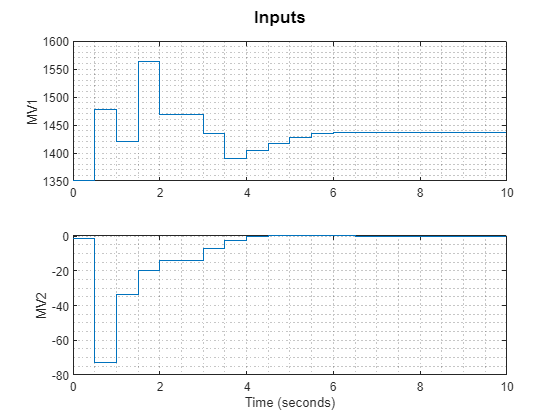

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

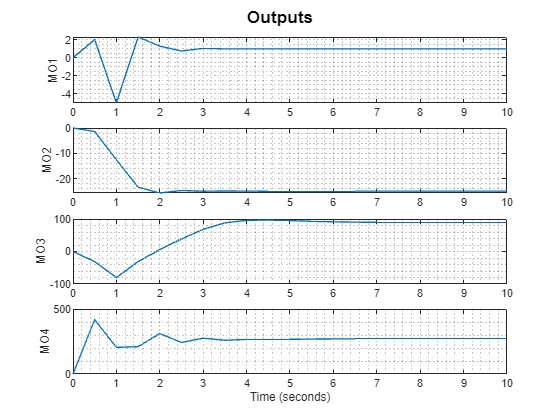


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

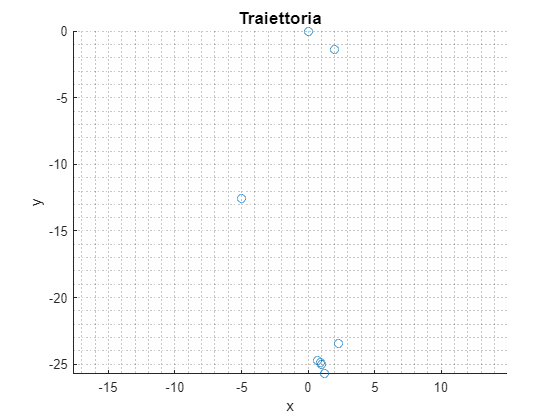


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione evidenziano la buona riuscita del controllo, con una traiettoria per il parcheggio caotica ma efficace.

Tuttavia, la prima uscita è soggetta ad una forte oscillazione e presenta un errore a regime non trascurabile.

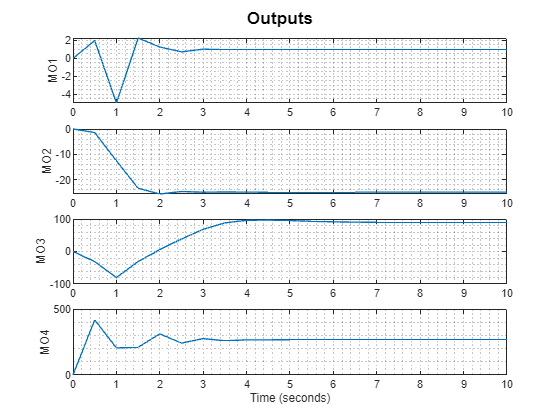

Una rapida analisi degli ingressi evidenzia valori impensabili per l'angolo di sterzata, che implicano rotazioni consecutive dello sterzo.

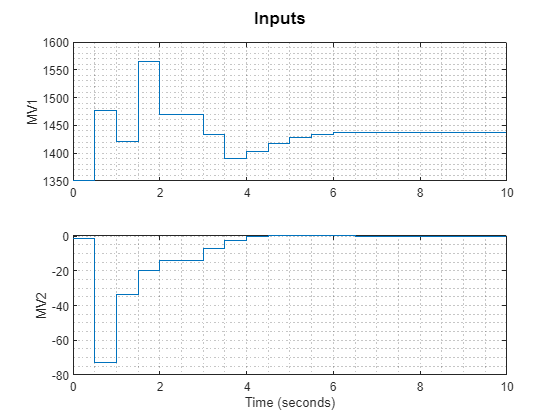

## Richiesta 3

Si vogliono imporre dei vincoli in modo da risolvere le principali problematiche evidenziate dalla simulazione del controllo.

### Definizione di vincoli sugli ingressi

L'angolo di sterzata deve essere limitato nel range $-45\le \alpha \le 45$ (quantità espresse in gradi), di conseguenza:

% Vincolo sul valore minimo dell'angolo di sterzata
nlmpcobj.ManipulatedVariables(1).Min = deg2rad(-45);

% Vincolo sul valore massimo dell'angolo di sterzta
nlmpcobj.ManipulatedVariables(1).Max = deg2rad(45);

La velocità longitudinale deve essere limitata nel range $-10\le v\le 10$, di conseguenza (anche se il vincolo sembra già soddisfatto:

% Vincolo sul valore minimo della velocità
nlmpcobj.ManipulatedVariables(2).Min = -10;

% Vincolo sul valore massimo della velocità
nlmpcobj.ManipulatedVariables(2).Max = 10;

L'angolo tra il camion ed il rimorchio deve essere limitato nel range $-90\le \theta \le 90$ (quantità espresse in gradi), di conseguenza:

% Vincolo sul valore minimo dell'angolo tra camion e rimorchio
nlmpcobj.OutputVariables(4).Min = deg2rad(-90);

% Vincolo sul valore massimo dell'angolo tra camion e rimorchio
nlmpcobj.OutputVariables(4).Max = deg2rad(90);

Si esegue nuovamente la simulazione per verificare se la modifica sui pesi associati alle uscite abbia effetto.

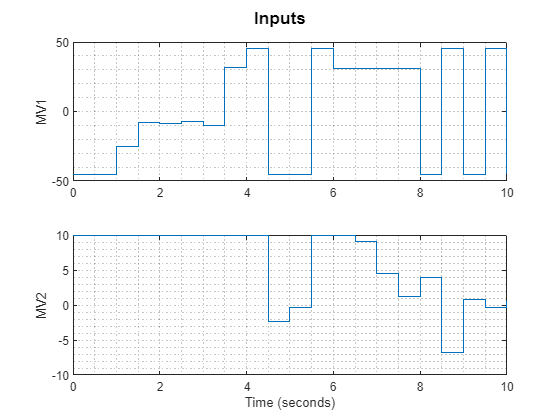

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

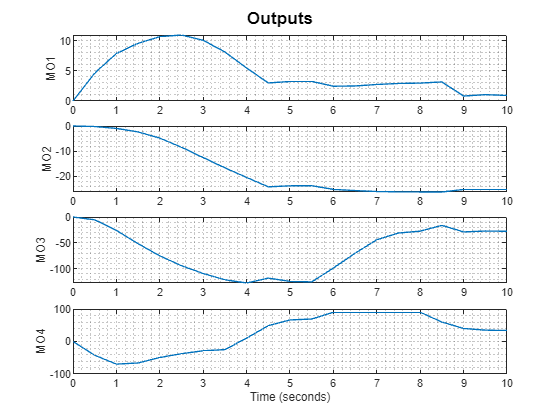


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

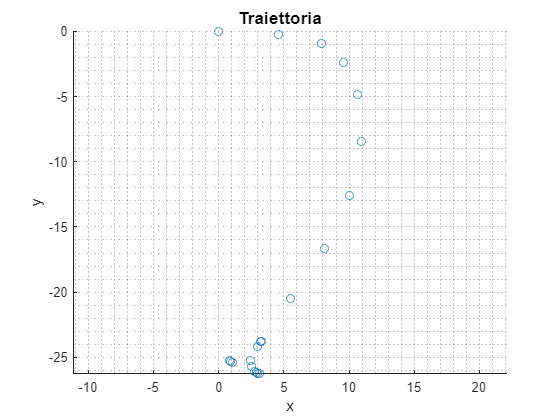


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione evidenziano il soddisfacimento dei vincoli ed un andamento più realistico della traiettoria. la buona riuscita del controllo, con una traiettoria per il parcheggio caotica ma efficace.

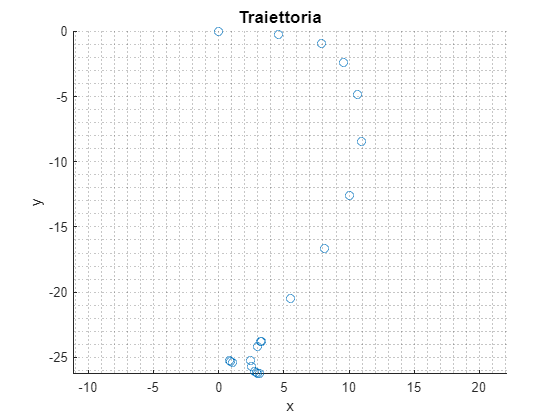

Le uscite assumono un andamento corretto, fatta eccezione per la terza uscita che assume valori molto lontani dal riferimento.

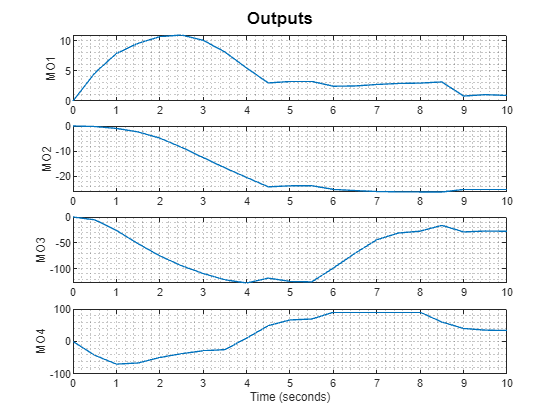

## Richiesta 4

Poiché la traiettoria seguita durante la manovra di parcheggio e la terza uscita non sono ancora del tutto soddisfacenti, si può pensare di agire ulteriormente sul controllore andando ad aumentare l'orizzonte di predizione e l'aggressività del controllo.

### Aumento dell'orizzonte di predizione

In primo luogo si aumenta l'orizzonte di predizione.

% Orizzonte di predizione
nlmpcobj.PredictionHorizon = Hp + 8;

Si esegue nuovamente la simulazione per verificare se l'incremento dell'orizzonte di predizione abbia effetto.

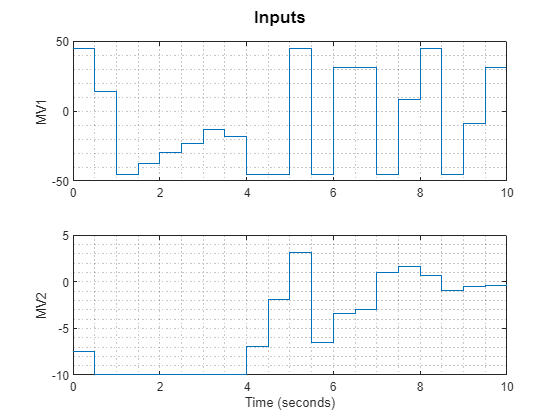

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

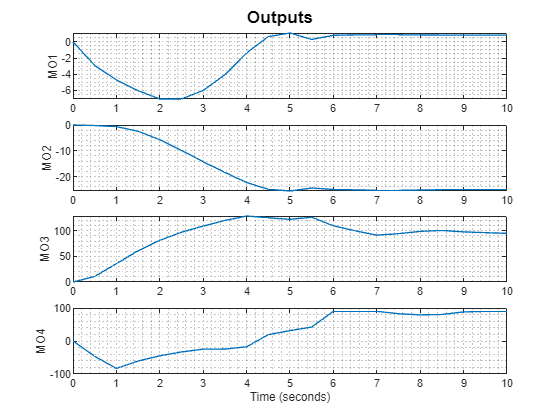


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

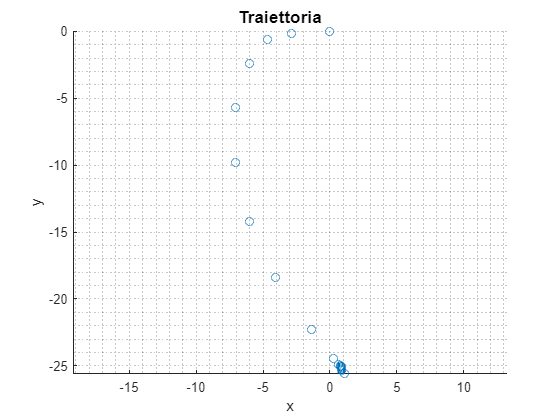


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione evidenziano un miglioramento nel controllo del sistema anche se l'errore sulla terza uscita è ancora importante.

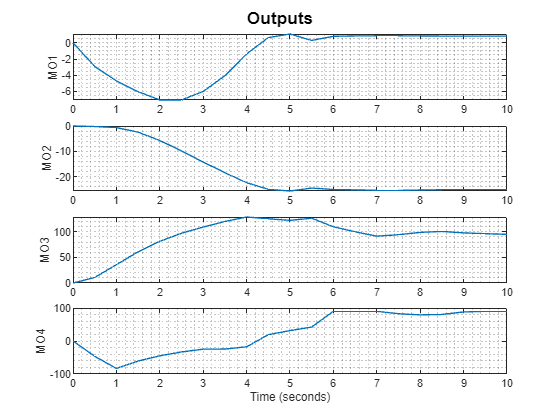

### Aumento dei pesi sulle uscite

In generale, le problematiche di controllo non sono proprio risolte. Si può pensare di aumentare l'aggressitività dell'azione di controllo aumentando i pesi associati alle variabili di uscita. In particolare, poiché la terza variabile di uscita è espressa in radianti, deve avere un peso maggiore rispetto a quello delle prime due variabili di uscita espresse in metri (e che quindi devono avere lo stesso peso).

% Peso associato alla prima uscita
nlmpcobj.Weights.OutputVariables(1) = 2;

% Peso associato alla seconda uscita
nlmpcobj.Weights.OutputVariables(2) = 2;

% Peso associato alla terza uscita
nlmpcobj.Weights.OutputVariables(3) = 6;

Si esegue nuovamente la simulazione per verificare se l'incremento dell'orizzonte di predizione abbia effetto.

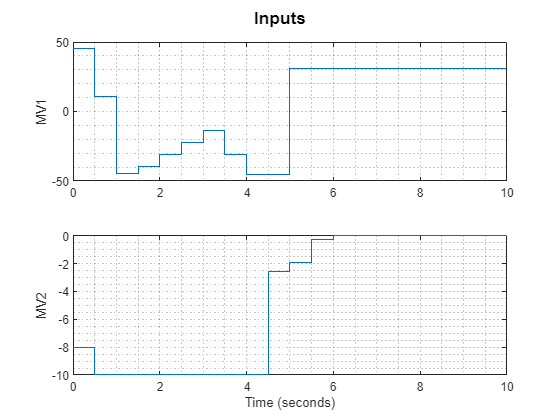

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

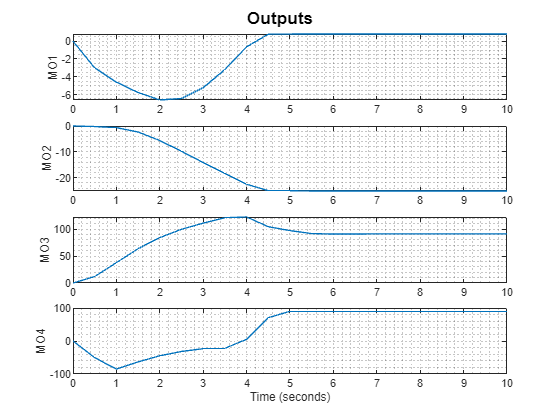


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

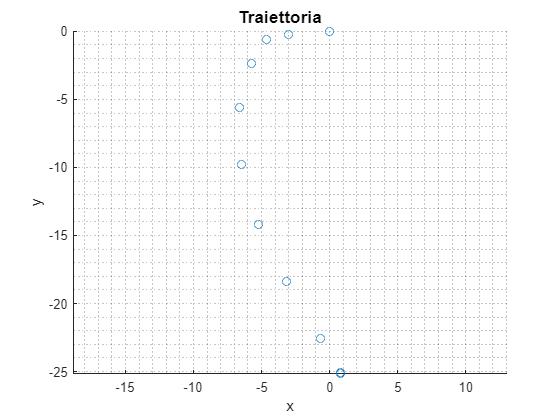


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione evidenziano come la maggiore aggressività del controllo riesca a soddisfare tutti i vincoli ulteriori, sia sul tempo di manovra minore di 6 secondi (tutte le uscite si assestano infatti in circa massimo 5 secondi) che sugli errori a regime, rispettivamente minori di 1 metro nel caso delle prime due variabili di uscita e di 1 grado nel caso della terza variabile di uscita.

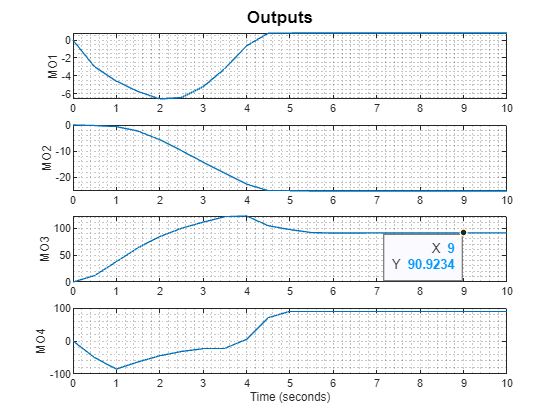

Il secondo ingresso di controllo (cioè la velocità longitudinale del camio) continua a saturare nonostante le migliorie apportate.

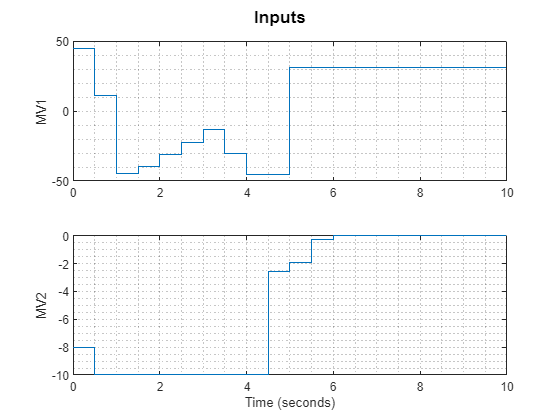

### Definizione di un vincolo sull'ingresso

Per minimizzare la velocità di parcheggio, si può pensare di definire un peso molto piccolo.

% Peso associato al secondo ingresso
nlmpcobj.Weights.ManipulatedVariables(2) = 0.05 ;

Si esegue nuovamente la simulazione per verificare se l'incremento dell'orizzonte di predizione abbia effetto.

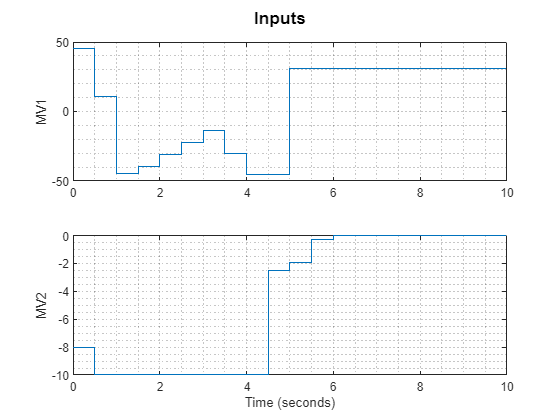

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
end

% Evoluzione degli ingressi
figure

for i=1:nu
    subplot(nu,1,i);
    if i==1
        stairs(t,rad2deg(u_history(i,:)));
    else
        stairs(t,u_history(i,:));
    end
    ylabel("MV" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Inputs', 'FontWeight', 'bold');

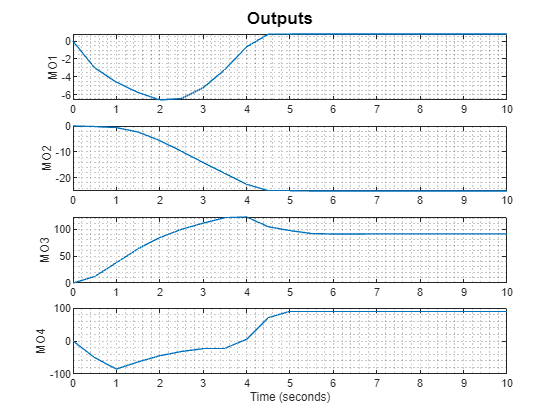


% Evoluzione delle uscite
figure

for i=1:ny
    subplot(ny,1,i);
    if i>=3
        plot(t,rad2deg(y_history(i,:)));
    else
        plot(t,y_history(i,:));
    end
    ylabel("MO" + i);
    grid minor
end
xlabel('Time (seconds)');

sgtitle('Outputs', 'FontWeight', 'bold');

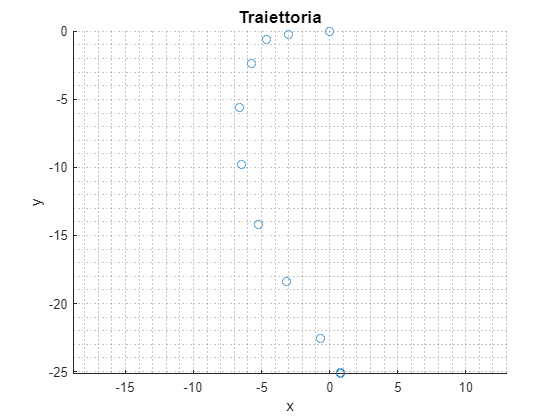


% Evoluzione della traiettoria
figure

scatter(y_history(1,:),y_history(2,:));
xlabel('x'), ylabel('y'), grid minor, axis equal;

sgtitle('Traiettoria', 'FontWeight', 'bold');

I risultati della simulazione evidenziano come il miglioramento apportato sia minimo, pur avendo reso molto più piccolo il peso associato al secondo ingresso, indice del fatto che non si possa fare molto altro per migliorare la situazione.

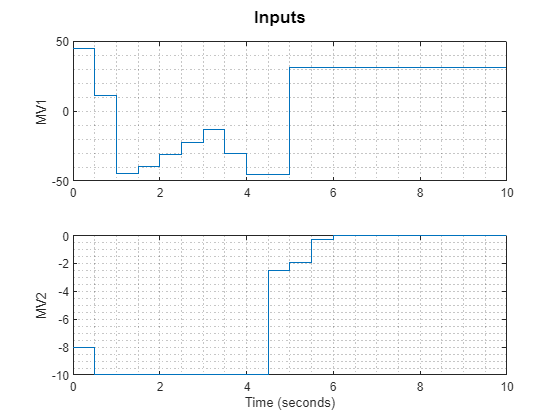

## Richiesta 5

Per l'analisi del tempo computazionale si utilizzano i comandi `tic` e `toc` per tenere traccia della durata dell'elaborazione di ciascun passo.

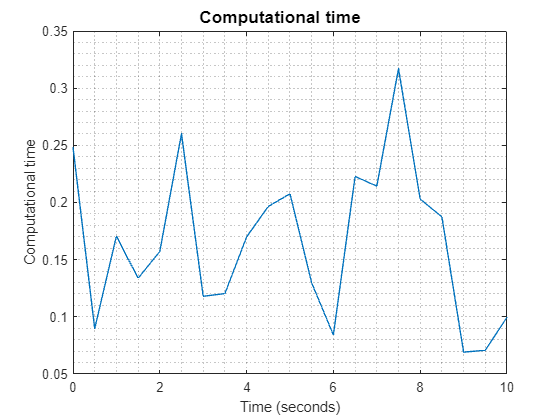

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Inizializzazione dei tempi computazionali
t_history(:,i) = zeros(1,N);

% Inizio conteggio
tic

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
    t_history(:,i) = toc;

    tic;
    
end

% Evoluzione del tempo computazionale
figure

plot(t,t_history(1,:));
xlabel('Time (seconds)'), ylabel('Computational time'), grid minor;

sgtitle('Computational time', 'FontWeight', 'bold');

I risultati della simulazione permettono di apprezzare un tempo computazionale molto contenuto, al di sotto del periodo di campionamento. Di conseguenza, è possibile affermare che il sistema composto da camion e rimorchio possa essere controllato in real time.

## Richiesta 6

Per l'analisi del costo si accede alla corrispettiva proprietà di `info`.

% Durata della simulazione
Tf = 10;

% Vettore dei tempi
t = 0:Ts:Tf;

% Step della simulazione
N = length(t);

% Inizializzazione
xk = zeros(4,1);
mv = zeros(2,1);

% Inizializzazione degli stati
x_history = zeros(4,N);

% Inizializzazione delle uscite
y_history = zeros(4,N);

% Inizializzazione degli ingressi
u_history = zeros(2,N);

% Inizializzazione dei costi
J_history(:,i) = zeros(1,N);

% Ciclo di controllo
for i=1:N

    [mv,~,info] = nlmpcmove(nlmpcobj,xk,mv,ref);

    % Controllo
    xk = info.Xopt(2,:);
    y = info.Yopt(1,:);
    J = info.Cost;

    % Aggiornamento
    x_history(:,i) = xk;
    y_history(:,i) = y;
    u_history(:,i) = mv;
    J_history(:,i) = J;
    
end

% Evoluzione del costo
figure

plot(t,t_history(1,:));
xlabel('Time (seconds)'), ylabel('Cost'), grid minor;

sgtitle('Cost', 'FontWeight', 'bold');

I risultati della simulazione restituiscono un costo che decresce esponenzialmente raggiungendo, in pochi secondi, dei valori molto bassi.